% %% choose audio file
clear all
close all



SNR=0;
ss=round(rand(1,1)*29)+1;
if ss<10
    sp=['0',num2str(ss)];
else
    sp=num2str(ss);
end
[dataC, fs] = audioread(strcat('clean\sp',sp,'.wav'));
o2=(rms(dataC)./10.^(0.1*SNR/2))^2;
t = (0:1/fs:(length(dataC)-1)/fs)';
data_noisy=dataC+randn(numel(dataC),1)*sqrt(o2);

## Processing

nnn=4;
q=[16,40,80];
win_t=[0.03,0.06,0.12];
iter=2;
        data{1}=KFO(data_noisy,fs,win_t(1),q(2),o2,1,dataC);
        data{2}=IMMO(data_noisy,fs,win_t(1),q(2),o2,1,dataC);
        data{3}=KFIT(data_noisy,fs,win_t(2),q(2),o2,iter);
        data{4}=IMMIT(data_noisy,fs,win_t(2),q(2),o2,iter);

## PLOT

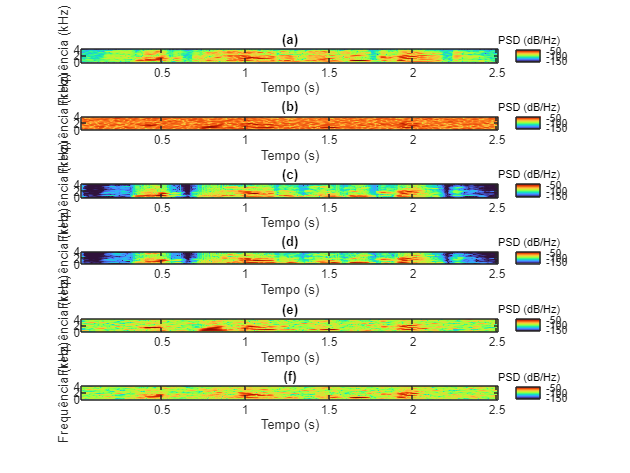

referencia={'(c)', '(d)','(e)','(f)','(g)','(h)','(i)','(j)'};

figure
subplot(nnn+2,1,1)
res=200;
alph=2*res;
bet=round(0.90*alph);
zet=5*res;
spectrogram(dataC,hamming(alph),bet,zet,fs,'yaxis');
title('(a)')
xlabel('Tempo (s)')
ylabel('Frequência (kHz)')
hcb=colorbar;
hcb.Title.String='PSD (dB/Hz)';
subplot(nnn+2,1,2)
spectrogram(data_noisy,hamming(alph),bet,zet,fs,'yaxis');

title('(b)')
xlabel('Tempo (s)')
ylabel('Frequência (kHz)')
hcb=colorbar;
hcb.Title.String='PSD (dB/Hz)';
colormap("Turbo")
for ii=1:nnn
    subplot(nnn+2,1,ii+2)
    spectrogram(data{ii},hamming(alph),bet,zet,fs,'yaxis');
    %     spectrogram(data{ii}-dataC,hamming(alph),bet,zet,fs,'yaxis');
    %     title(['q = ',num2str(q(ii))])
    title(referencia{ii})
    xlabel('Tempo (s)')
    ylabel('Frequência (kHz)')
    hcb=colorbar;
    hcb.Title.String='PSD (dB/Hz)';
    %     title(['win_t size = ',num2str(win_t(ii)*1000),' ms'])

    colormap("Turbo")
end

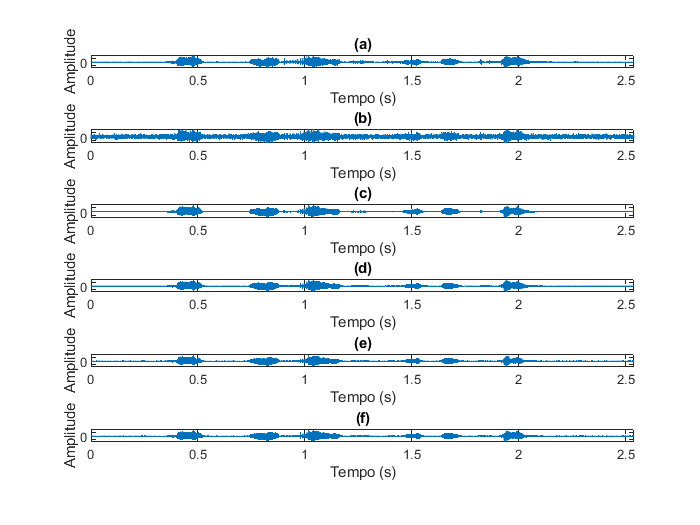

% sound(data{2}/rms(data{2})/100)

figure
subplot(nnn+2,1,1)
plot(t,dataC);
xlim([t(1),t(end)])
ylim([min(dataC)*1.1,max(dataC)*1.1])
title('(a)')
xlabel('Tempo (s)')
ylabel('Amplitude')

subplot(nnn+2,1,2)
plot(t,data_noisy);
xlim([t(1),t(end)])
ylim([min(dataC)*1.1,max(dataC)*1.1])
title(['(b)'])
colormap("Turbo")
xlabel('Tempo (s)')
ylabel('Amplitude')

for ii=1:nnn
    subplot(nnn+2,1,ii+2)
    %     plot(data{ii});
    plot(t,data{ii});
    %     title(['KFIt ord =',num2str(q(ii))])
    %     title(['win_t size = ',num2str(win_t(ii)*1000),' ms'])
    title(referencia{ii})
    colormap("Turbo")
    xlim([t(1),t(end)])
    ylim([min(dataC)*1.1,max(dataC)*1.1])
    xlabel('Tempo (s)')
    ylabel('Amplitude')

end
xlim([t(1),t(end)])

## Métricas

zSNR{1}=20*log10(rms(dataC)/rms(dataC-data_noisy));
zPESQ{1}=pesq(dataC,data_noisy,fs);
for ii=1:nnn
    zSNR{ii+1}=20*log10(rms(dataC)/rms(dataC-data{ii}));
    zPESQ{ii+1}=pesq(dataC,data{ii},fs);
end
zSNR

zSNR = 1×5 cell array
    {[0.0632]}    {[10.7661]}    {[11.3413]}    {[9.1520]}    {[9.6641]}


zPESQ

zPESQ = 1×5 cell array
    {[1.6724]}    {[2.9423]}    {[2.9316]}    {[2.1525]}    {[2.2177]}


## Sound

s=[cell2mat(data)];
snd=s(1:end);
sound(snd/rms(snd)/20,fs)